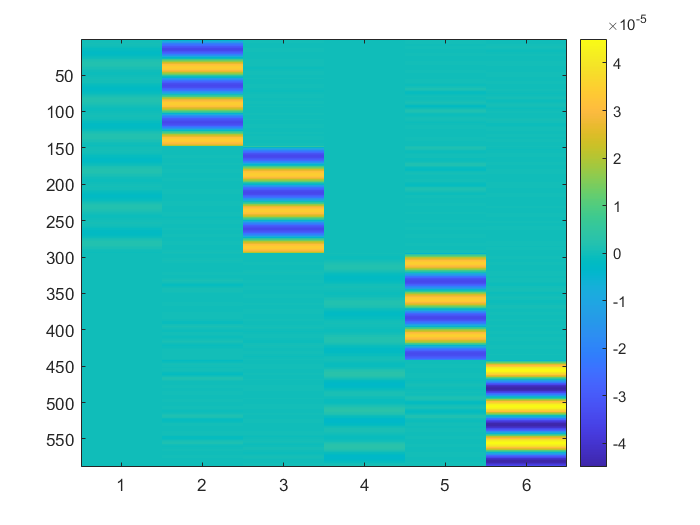

eqa = importdata('../../temp/eq_a_20211202182547.txt'); 
diff_eqa = diff(eqa, 1, 1); diff_diff_eqa = diff(diff_eqa, 1, 1); diff_diff_diff_eqa = diff(diff_diff_eqa, 1, 1); diff_diff_diff_diff_eqa = diff(diff_diff_diff_eqa, 1, 1);
eqb = importdata('../../temp/eq_b_20211202182547.txt'); diff_eqb = diff(eqb);

pc_a = [1.50; 0.00004; 0.00004];
pc_b = [1.50; 0.00004; 0.00004];

t = 0: 5: 86400 - 5;
alt_angle_sin = deg2rad(2 + 1 * sin(2 * pi / 250 * t))';
phase_centre_simu = pc_a(1) + pc_b(1) * cos(alt_angle_sin) - pc_b(3) * sin(alt_angle_sin); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu); diff_diff_diff_simu = diff(diff_diff_simu); diff_diff_diff_diff_simu = diff(diff_diff_diff_simu);
phase_centre_simu = importdata('../../temp/simu86400/simu_86400.txt'); diff_simu = diff(phase_centre_simu); diff_diff_simu = diff(diff_simu);
% phase_centre_simu = eqa(:, 1: 3) * pc_b + eqa(:, 4: 6) * pc_a; diff_simu = diff(phase_centre_simu);
% diff_eqb = diff_eqb + diff_simu;
diff_diff_eqb = diff(diff_eqb); 
diff2_eqa = [diff(diff(eqa(1: 200, :))); diff(diff(eqa(201: 400, :))); diff(diff(eqa(401: 600, :))); diff(diff(eqa(601: 800, :)))];
diff2_eqb = [diff(diff(eqb(1: 200))); diff(diff(eqb(201: 400))); diff(diff(eqb(401: 600))); diff(diff(eqb(601: 800)))];
diff3_eqa = [diff(diff(diff(eqa(1: 200, :)))); diff(diff(diff(eqa(201: 400, :)))); diff(diff(diff(eqa(401: 600, :)))); diff(diff(diff(eqa(601: 800, :))))];
diff3_eqb = [diff(diff(diff(eqb(1: 200)))); diff(diff(diff(eqb(201: 400)))); diff(diff(diff(eqb(401: 600)))); diff(diff(diff(eqb(601: 800))))];

start = 1;
len = 197;
end_s = len + start - 1;
eqa1 = filter_pdfree(Num, diff3_eqa(start: end_s, :));
eqa2 = filter_pdfree(Num, diff3_eqa(end_s * 1 + 1: end_s * 1 + len, :));
eqa3 = filter_pdfree(Num, diff3_eqa(end_s * 2 + 1: end_s * 2 + len, :));
eqa4 = filter_pdfree(Num, diff3_eqa(end_s * 3 + 1: end_s * 3 + len, :));
eqb1 = filter_pdfree(Num, diff3_eqb(start: end_s));
eqb2 = filter_pdfree(Num, diff3_eqb(end_s*1 + 1: end_s*1 + len));
eqb3 = filter_pdfree(Num, diff3_eqb(end_s*2 + 1: end_s*2 + len));
eqb4 = filter_pdfree(Num, diff3_eqb(end_s*3 + 1: end_s*3 + len));
eqa_all = [eqa1; eqa2; eqa3; eqa4];
eqb_all = [eqb1; eqb2; eqb3; eqb4];
eqb_normal = eqa_all' * (eqb_all);
eqa_normal = eqa_all' * eqa_all;
imagesc(eqa_all); colorbar

cond(eqa_normal)

ans =     710.546911150687e+000


bbbb = pcg(eqa_normal, eqb_normal)

pcg converged at iteration 6 to a solution with relative residual 3.6e-12.


bbbb =     1.49158795097250e+000
    19.8257321977070e-003
    29.7772621034049e-003
   -1.04364582861960e+000
   -45.8148276168274e-003
   -34.7086348190086e-003


acos(dot(bbbb(1: 3), [1.49; 0.02; 0.03]) / (norm(bbbb(1: 3)) * norm([1.49; 0.02; 0.03])))

ans =     215.174958844033e-006


acos(dot(bbbb(4: 6), pc_b) / (norm(bbbb(4: 6)) * norm(pc_b)))

ans =     3.08661162686993e+000


lsqr converged at iteration 3 to a solution with relative residual 0.014.
lsqr converged at iteration 3 to a solution with relative residual 0.014.
lsqr converged at iteration 3 to a solution with relative residual 0.014.
lsqr converged at iteration 3 to a solution with relative residual 0.017.
lsqr converged at iteration 3 to a solution with relative residual 0.017.
lsqr converged at iteration 3 to a solution with relative residual 0.017.
lsqr converged at iteration 3 to a solution with relative residual 0.022.
lsqr converged at iteration 3 to a solution with relative residual 0.022.
lsqr converged at iteration 3 to a solution with relative residual 0.022.


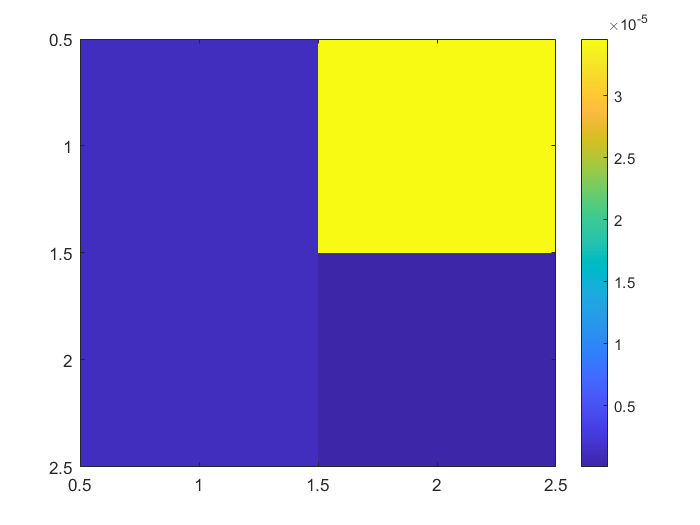

lsqr converged at iteration 2 to a solution with relative residual 1.1e-10.


cccc = zeros(6, 1);
cccc([1 2]) = solver_spectral(eqa1, eqb1, [1 2], 0.2);

lsqr converged at iteration 3 to a solution with relative residual 0.0045.
lsqr converged at iteration 3 to a solution with relative residual 0.0045.
lsqr converged at iteration 3 to a solution with relative residual 0.0045.
lsqr converged at iteration 3 to a solution with relative residual 0.0062.
lsqr converged at iteration 3 to a solution with relative residual 0.0062.
lsqr converged at iteration 3 to a solution with relative residual 0.0062.
lsqr converged at iteration 3 to a solution with relative residual 0.011.
lsqr converged at iteration 3 to a solution with relative residual 0.011.
lsqr converged at iteration 3 to a solution with relative residual 0.011.


lsqr converged at iteration 2 to a solution with relative residual 2.7e-10.


cccc([1 3]) = solver_spectral(eqa2, eqb2, [1 3], 0.2);

lsqr converged at iteration 3 to a solution with relative residual 0.01.
lsqr converged at iteration 3 to a solution with relative residual 0.01.
lsqr converged at iteration 3 to a solution with relative residual 0.01.
lsqr converged at iteration 3 to a solution with relative residual 0.013.
lsqr converged at iteration 3 to a solution with relative residual 0.013.
lsqr converged at iteration 3 to a solution with relative residual 0.013.
lsqr converged at iteration 3 to a solution with relative residual 0.026.
lsqr converged at iteration 3 to a solution with relative residual 0.026.
lsqr converged at iteration 3 to a solution with relative residual 0.026.


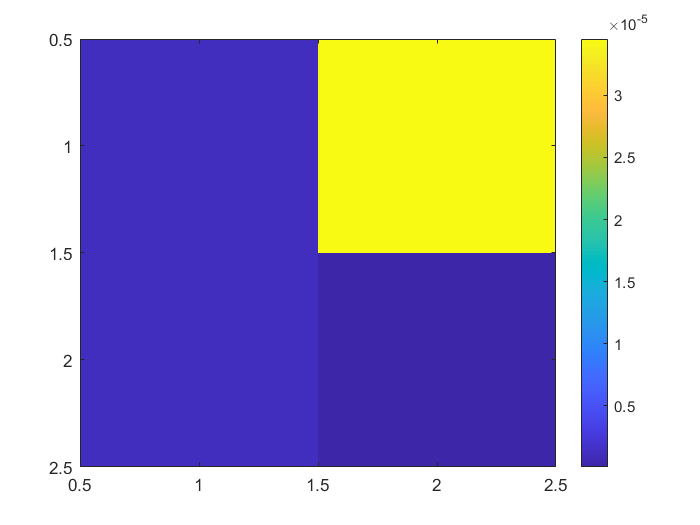

lsqr converged at iteration 2 to a solution with relative residual 6.8e-11.


cccc([4 5]) = solver_spectral(eqa3, eqb3, [4 5], 0.2);

lsqr converged at iteration 3 to a solution with relative residual 0.0043.
lsqr converged at iteration 3 to a solution with relative residual 0.0043.
lsqr converged at iteration 3 to a solution with relative residual 0.0043.
lsqr converged at iteration 3 to a solution with relative residual 0.0066.
lsqr converged at iteration 3 to a solution with relative residual 0.0066.
lsqr converged at iteration 3 to a solution with relative residual 0.0066.
lsqr converged at iteration 3 to a solution with relative residual 0.011.
lsqr converged at iteration 3 to a solution with relative residual 0.011.
lsqr converged at iteration 3 to a solution with relative residual 0.011.


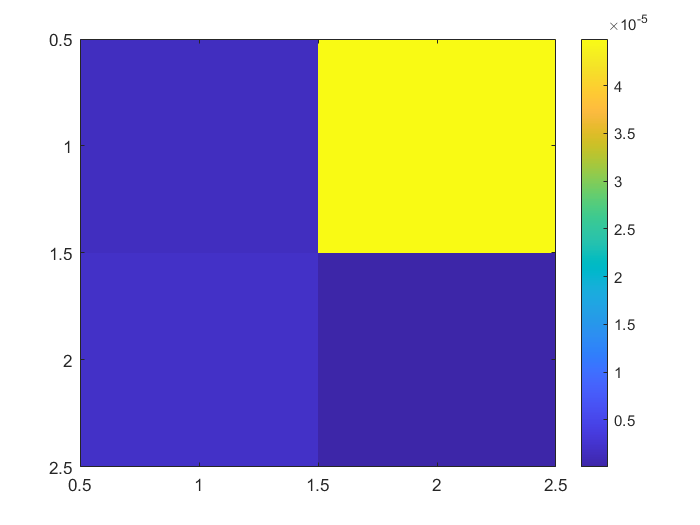

lsqr converged at iteration 2 to a solution with relative residual 5.8e-12.


cccc([4 6]) = solver_spectral(eqa4, eqb4, [4 6], 0.2);

cccc

cccc =     1.48842883310054e+000
    19.8348534529441e-003
    29.9663185275143e-003
    882.053433311962e-003
    29.9182696866248e-003
    40.2715802229219e-003


acos(dot(cccc(1: 3), [1.49; 0.02; 0.03]) / (norm(cccc(1: 3)) * norm([1.49; 0.02; 0.03])))

ans =     96.7571329870226e-006


acos(dot(cccc(4: 6), pc_b) / (norm(cccc(4: 6)) * norm(pc_b)))

ans =     56.7786956325379e-003
